# 插值

1、通过离散傅里叶变换的平移/调制性质得到

2、通过离散傅里叶变换的频谱补零得到

3、通过与插值核的卷积得到√

sinc插值

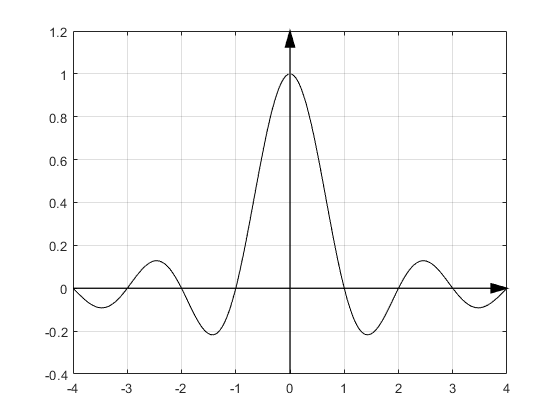

% 插值核
N = 40;
t = -4:1/N:4-1/N;

st = sin(pi*t)./(pi*t);

figure
plot(t,st,'k')
axis([-4 4,-0.4 1.2])
grid on

% 坐标轴
arrow([-4,0],[4,0],'Color','k','Linewidth',1);
arrow([0,-0.4],[0,1.2],'Color','k','Linewidth',1);

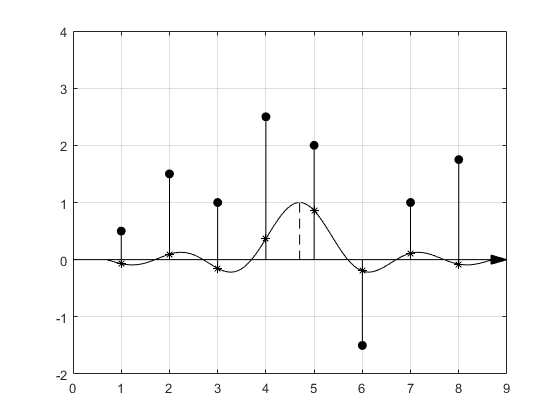


% 初始样本
x2 = 1:8;

gx = [1,3,2,5,4,-3,2,3.5]/2;

figure
plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
axis([0 9,-2 4])
grid on

for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k');
end

% 坐标轴
arrow([0,0],[9,0]);

a = 4.7;

plot(t+a,st,'k'),hold on,plot(x2,sinc(x2-a),'k*')

for i = 1:8
    line([x2(i),x2(i)],[sinc(i-a),0],'Color','k');
end

line([a,a],[sinc(0),0],'Color','k','LineStyle','--')


H = [];
%% 插值运算
a = 1:1/2:8-1/2

a =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000


for a = 1:1/2:8-1/2
    t1 = a-4:1:a+3;
    sinc(t1)
end

ans =     0.0000   -0.0000    0.0000    1.0000    0.0000   -0.0000    0.0000   -0.0000


ans =     0.1273   -0.2122    0.6366    0.6366   -0.2122    0.1273   -0.0909    0.0707


ans =    -0.0000    0.0000    1.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000


ans =    -0.2122    0.6366    0.6366   -0.2122    0.1273   -0.0909    0.0707   -0.0579


ans =     0.0000    1.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000


ans =     0.6366    0.6366   -0.2122    0.1273   -0.0909    0.0707   -0.0579    0.0490


ans =     1.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000


ans =     0.6366   -0.2122    0.1273   -0.0909    0.0707   -0.0579    0.0490   -0.0424


ans = 	1.0e+-16 *

    0.3898   -0.3898    0.3898   -0.3898    0.3898   -0.3898    0.3898   -0.3898


ans =    -0.2122    0.1273   -0.0909    0.0707   -0.0579    0.0490   -0.0424    0.0374


ans = 	1.0e+-16 *

   -0.3898    0.3898   -0.3898    0.3898   -0.3898    0.3898   -0.3898    0.3898


ans =     0.1273   -0.0909    0.0707   -0.0579    0.0490   -0.0424    0.0374   -0.0335


ans = 	1.0e+-16 *

    0.3898   -0.3898    0.3898   -0.3898    0.3898   -0.3898    0.3898   -0.3898


ans =    -0.0909    0.0707   -0.0579    0.0490   -0.0424    0.0374   -0.0335    0.0303



A = figure();
plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
axis([0 9,-2 4])
grid on

for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k')
end

% 坐标轴
arrow([0,0],[9,0]);

for b = 1:1/N:8-1/N
    t2 = b-1:-1:b-8;
    gx_f = sinc(t2)*gx';
    figure(A)
    plot(b,gx_f,'k.'),hold on
    
    if b == a
       plot(b,gx_f,'kd'),hold on
       line([b,b],[gx_f,0],'Color','k','LineStyle','--')
    end
end

%% 绘图
set(figure,'position',[100,100,1200,1200]);

subplot(311),plot(t,st,'k')
title('(a)插值核'),xlabel('x1'),ylabel('hx')
axis([-4 4,-0.4 1.2])
grid on
arrow([-4,0],[4,0],'Color','k','Linewidth',1);
arrow([0,-0.4],[0,1.2],'Color','k','Linewidth',1);

subplot(312),plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
plot(t+a,st,'k'),hold on
plot(x2,sinc(x2-a),'k*'),hold on 
title('(a)插值运算'),xlabel('x2'),ylabel('gx')
axis([0 9,-2 4])
grid on
for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k');
end
for i = 1:8
    line([x2(i),x2(i)],[sinc(i-a),0],'Color','k');
end
line([a,a],[sinc(0),0],'Color','k','LineStyle','--')
arrow([0,0],[9,0]);

subplot(313),plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
title('(a)插值后的信号'),xlabel('x2'),ylabel('gx_f')
axis([0 9,-2 4])
grid on
for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k')
end
for b = 1:1/N:8-1/N
    t2 = b-1:-1:b-8;
    gx_f = sinc(t2)*gx';
    plot(b,gx_f,'k.'),hold on
    if b == 4.7
       plot(b,gx_f,'kd'),hold on
       line([b,b],[gx_f,0],'Color','k','LineStyle','--')
    end
end
arrow([0,0],[9,0]);

suptitle('图2.14 使用sinc函数插值的图')


插值核的归一化

对于截断后的核，需要进行归一化处理，使其增益单位化，否则采样点上的权值和不再等于1，并且在不同插值点x之间存在差异。

插值核的加权

当使用截断后的插值核对存在陡峭边缘的函数进行插值时，会出现一种称为Gibbs效应的振铃现象。为减小这种影响，应对插值核进行锐化窗加权。

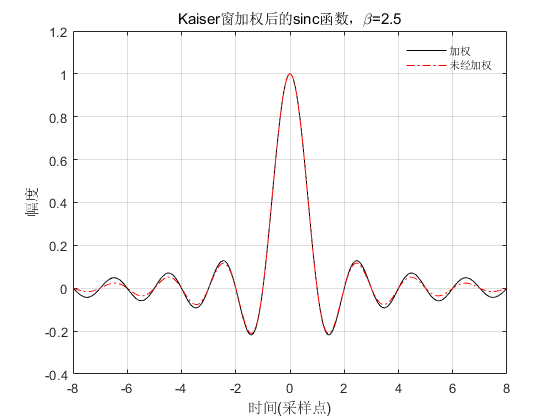

N = 500;
t = -8:1/N:8-1/N;

st = sin(pi*t)./(pi*t);

figure
p1 = plot(t,st,'k');hold on
p2 = plot(t,st.*kaiser(length(t),2.5)','r-.');% kaiser窗加权
title('Kaiser窗加权后的sinc函数，\beta=2.5'),xlabel('时间(采样点)'),ylabel('幅度')
axis([-8 8,-0.4 1.2])
grid on

legend('boxoff');
lgd = legend([p1,p2],{'加权','未经加权'},'FontSize',8,'TextColor','k','Location','northeast','NumColumns',1);

% title(lgd,'My Legend Title')

为提高计算效率，可以将升采样后的插值核存储在表格中，这样就无需对每个插值点计算sinc函数、窗和归一化因子，

而只需使用最接近移动位置处的表格系数。


t2 =

  空的 1×0 double 行向量

